# **RT-QIBC**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);
impath = fullfile(dataDir,'C205_Images\');


dat = m.S(1,2);
dat = dat{1};
gate = m.gates_all(1,2);
gate = gate{1};
medEdU = m.medEdU_all(1,2);

**check EdU Cdt1 Geminin time since crl4**

conds=[1 2];
poiAligned=3;
offset=0;
% f0 = figure('pos',[10 10 400*length(conds) 800 ]);
% f1 = figure('pos',[10 10 400*3 300 ]);
f2 = figure('units','inches','Position',[0 0 4 4]);
hold on
% f3 = figure('units','inches','Position',[0 0 4 4]);
% hold on
gateVals = {{},{'YFP2'}};
rangeVals = {{[]},{[2^8 2^10]}};

edges = (0:(1/dat(1).framesPerHr):2);


for i=1:length(conds)
    ind= ~isnan(dat(conds(i)).POI_time(:,poiAligned)) & ...
        gate_vals(dat(conds(i)), gateVals{i}, rangeVals{i}) & dat(conds(i)).POI_time(:,poiAligned) <=2;
    
    xdata = dat(conds(i)).POI_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = (dat(conds(i)).YFP1(ind));
    ydata(:, 2) = (dat(conds(i)).YFP2(ind));
    ydata(:, 3) = (dat(conds(i)).FarRed1(ind)) ;
    
    
    threshs ={{gate.YFP1_S(2), -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',edges);
    midpoints = edges + (edges(2) -edges(1))/2;
    midpoints = midpoints(1:end-1);
    
%     figure(f0)
%     subplot(3,length(conds),i), hold on
%     scatter(xdata,(ydata(:,1)),25,'k','filled','MarkerFaceAlpha',.1);
%     plot(midpoints,(binData(1).median),'r');
%     ylim([0 1000]);
%     xlim([0 2]);
%     ylabel('Cdt1 (AU)');
%     title(dat(1).conditions{conds(i),1});
%     hline((gate.YFP1_S),'k');
%     hold off
%     
%     subplot(3,length(conds),i+length(conds)), hold on
%     scatter(xdata,(ydata(:,2)),25,'k','filled','MarkerFaceAlpha',.1);
%     plot(midpoints,(binData(2).median),'r');
%     ylim([0 1000]);
%     xlim([0 2]);
%     ylabel('GMNN (AU)');
%     title(dat(1).conditions{conds(i),1});
%     hline((gate.YFP2_G1),'k');
%     hold off
%     
%     subplot(3,length(conds),i+2*length(conds)), hold on
%     scatter(xdata,(ydata(:,3)),25,'k','filled','MarkerFaceAlpha',.1);
%     plot(midpoints,(binData(3).median),'r');
%     ylim([0 12000]);
%     xlim([0 2]);
%     ylabel('EdU (AU)');xlabel('Time since S phase start (hrs)');
%     title(dat(1).conditions{conds(i),1});
%     hline(gate.FarRed1_G1,'k');
%     hold off
    
%     figure(f1)
%     subplot(1,3,1), hold on
%     errorbar(midpoints, binData(1).mean, 2*binData(1).sem,'LineWidth',1)
%     xlabel('Time since S phase start (hrs)');
%     ylabel('Mean Cdt1');
%     hline(gate.YFP1_S,'k');
%     xlim([0 2]);
%     %legend(dat(1).conditions(conds,1))
%     
%     subplot(1,3,2), hold on
%     errorbar(midpoints, binData(2).mean, 2*binData(2).sem,'LineWidth',1)
%     xlabel('Time since S phase start (hrs)');
%     ylabel('Mean GMNN');
%     xlim([0 2]);
%     hline(gate.YFP2_G1,'k');
%     
%     subplot(1,3,3), hold on
%     errorbar(midpoints, binData(3).perc, 2*binData(3).percerr,'LineWidth',1)
%     xlabel('Time since S phase start (hrs)');
%     ylabel('Frac EdY +');
%     xlim([0 2]);
%     hline(.5,'k');
    
    figure(f2)
    errorbar(midpoints, binData(1).mean, 2*binData(1).sem,'LineWidth',1)
    xlabel('Time since S phase start (hrs)');
    ylabel('Cdt1 (RFU)');
    hline(gate.YFP1_S(2),'k');
    xlim([0 2]);
     xticks([0:.5:2])
    axis square
    %legend(dat(1).conditions(conds,1))
    min(binData(1).numCells(binData(1).numCells >0))
    sum(binData(1).numCells)
       

%     figure(f3)
%     errorbar(midpoints, binData(1).mean/binData(1).mean(5), 2*binData(1).sem/binData(1).mean(5),'LineWidth',1)
%     xlabel('Time since S phase start (hrs)');
%     ylabel('Cdt1 (Norm)');
% %     hline(gate.YFP1_S,'k');
%     xlim([0 2]);
%     xticks([0:.5:2])
%     axis square
end

ans = 61

ans = 3436

ans = 32

ans = 2302

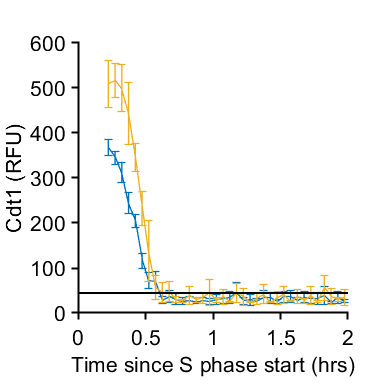

 figure(f2)
 print_pdf([pwd() '\Figs\C205_Cdt1_deg_compare.pdf'])

**Plot Cdt1 levels DMSO**

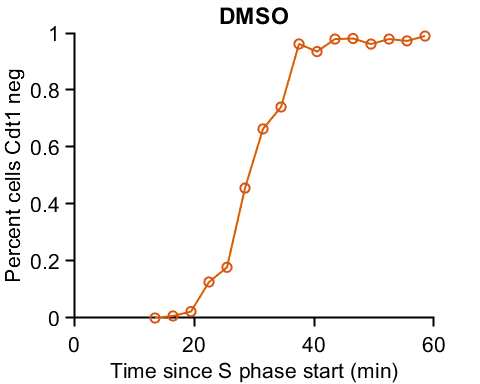

ans =    105   140    88    95   298   204   101    77    78    92    94   103   103    94   108    93


ans = 77

ans = 1873

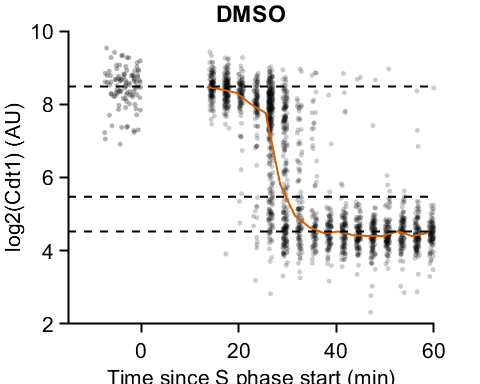

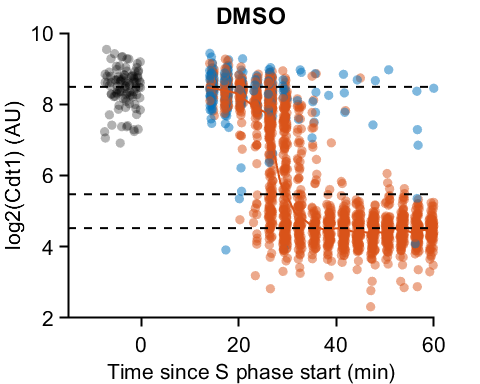

conds=[1];
poiAligned=3;
offset=-1;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);

gateVals = {{}};
rangeVals = {{}};

% range = linspace(0,4,10);
edges = (.2:1/dat(1).framesPerHr:1);
midpoints = edges + (edges(2) -edges(1))/2;
midpoints = midpoints(1:end-1);

for i=1:length(conds)
    ind= gate_vals(dat(conds(i)), gateVals{i}, rangeVals{i}) & dat(conds(i)).POI_time(:,poiAligned) <=1;
    
    xdata = dat(conds(i)).POI_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = log2(dat(conds(i)).YFP1(ind));
    ydata(:, 2) = log2(dat(conds(i)).YFP2(ind));
    ydata(:, 3) = log2(dat(conds(i)).FarRed1(ind)) ;
    
    
    threshs ={{log2(gate.YFP1_S(2)), -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',edges);
    
        binData(1).numCells
    min(binData(1).numCells)
    length(xdata)
    
    %%% Get G1 levels
    inds = dat(conds(i)).POI_time(:,1) <= 2 & dat(conds(i)).POI_time(:,1) > 1 &...
        isnan(dat(conds(i)).POI(:,3));
    g1Y = log2(dat(conds(i)).YFP1(inds));
    subsinds = randsample(length(g1Y),100);
    g1Y = g1Y(subsinds);
    jitterX = rand(size(g1Y))*.125 - 0.125;
    
     %%% Plot black and colored by Cdt1 levels
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
    hold on
    scatter(xdata*60,ydata(:,1),15,'k','filled','MarkerFaceAlpha',.2);
    plot(midpoints*60,binData(1).median,'LineWidth',1.5,'Color',[213 94 0]/255);
    ylim([2 10]);
    xlim([-.25 1]*60);
    ylabel('log2(Cdt1) (AU)');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
    h=hline(log2([gate.YFP1_S gate.YFP1_G1(2)]),'k--');
    scatter(jitterX*60,g1Y,15,'k','filled','MarkerFaceAlpha',.3);
    pbaspect([1.25 1 1])
    print_pdf([pwd() '\Figs\C205_Cdt1_time.pdf'])
    
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
    hold on
    eduneg = ydata(:,3) < log2(gate.FarRed1_G1(2));
    edupos = ydata(:,3) >= log2(gate.FarRed1_G1(2));
    colors = zeros(length(eduneg),3);
    colors(eduneg,:) = repmat([0 0.4470 0.7410],sum(eduneg),1);
    colors(edupos,:) = repmat([0.8500 0.3250 0.0980],sum(edupos),1);
    scatter(xdata*60,ydata(:,1),50,colors,...
        'filled','MarkerFaceAlpha',.5);
    plot(midpoints*60,binData(1).median,'LineWidth',1.5);
    scatter(jitterX*60,g1Y,50,'k','filled','MarkerFaceAlpha',.3);
    %ylim([4 10]);
    xlim([-.25 1]*60);
    ylabel('log2(Cdt1) (AU)');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
    h=hline(log2([gate.YFP1_S gate.YFP1_G1(2)]),'k--');
    
    figure(f1)
    hold on
    plot(midpoints*60,binData(1).perc,'LineWidth',1.5,'Color',[213 94 0]/255);
    scatter(midpoints*60,binData(1).perc,50,'LineWidth',1.5);
    ylabel('Percent cells Cdt1 neg');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
    xlim([0 60])
    ylim([0 1])
    %cells = length(xdata)
    
end

## Compare geminin levels 

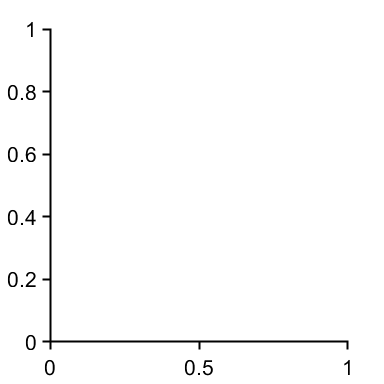

%%% 1-2 hr post mitosis
conds=[1 2];
figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on

g1 = {};
for i=1:length(conds)
    c = conds(i);
    inds = dat(c).POI_time(:,1) > 1 &  dat(c).POI_time(:,1) <= 2 ;
    g1{i} = dat(c).YFP2(inds);
    g1{i}(g1{i}< 1) = [];
    g1{i} = log2(g1{i});
end

% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^8 & dat(condition).allFarRed1 < 2^11;
g1{3} = dat(condition).allYFP2(ind);
g1{3}(g1{3}< 1) = [];
g1{3} = log2(g1{3});

% nhist(g1, 'npoints',   'samebins', 'noerror','legend',{dat(1).conditions{conds,1}, 'G2'},'fsize',16)
% title([dat(1).experiment ' G1 phase'])
% xlabel('log2(GMNN) (AU)')
% pbaspect([1 1 1])
% print_pdf([pwd() '\Figs\C205_gmnn_over_hist_G1.pdf'])

% g1dmso = g1{1};
% g1dox = g1{2};
% g1dmso = g1dmso(~isnan(g1dmso));
% g1dox = g1dox(~isnan(g1dox));
% [h,p,ci,stats] = ttest2(g1dmso,g1dox)

%%% S phase start
conds=[1 2];
% figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
s = {};
for i=1:length(conds)
    c = conds(i);
    inds = dat(c).POI_time(:,3) <= .5;
    s{i} = dat(c).YFP2(inds);
    s{i}(s{i}< 1) = [];
    s{i} = log2(s{i});
end

% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^8 & dat(condition).allFarRed1 < 2^11;
s{3} = dat(condition).allYFP2(ind);
s{3}(s{3}< 1) = [];
s{3} = log2(s{3});

% nhist(s, 'npoints',   'samebins', 'noerror','legend',{dat(1).conditions{conds,1}, 'G2'},'fsize',16)
% title([dat(1).experiment ' S phase'])
% xlabel('log2(GMNN) (AU)')
% pbaspect([1 1 1])
% print_pdf([pwd() '\Figs\C205_gmnn_over_hist_S.pdf'])

% sdmso = s{1};
% sdox = s{2};
% sdmso = sdmso(~isnan(sdmso));
% sdox = sdox(~isnan(sdox));
% [h,p,ci,stats] = ttest2(sdmso,sdox)

all_cell = [g1(1:2) s]';
all_cell = cellfun(@(x) randsample(x,min([2000 length(x)])),all_cell,'UniformOutput',false);
ally = cell2mat(all_cell);
group = [];    
for i=1:length(all_cell)
    group = [group; i*ones(size(all_cell{i}))];
    size(all_cell{i})
end

ans =         2000           1


ans =         2000           1


ans =    928     1


ans =    816     1


ans =         1284           1


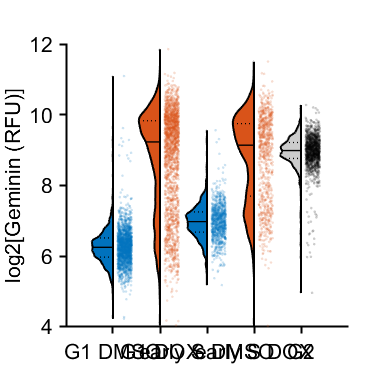


inds = ally > 4;
ally = ally(inds);
group = group(inds);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1 DMSO','G1 DOX','early S DMSO','early S DOX','G2'});
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [cols([1 2 1 2],:);[0 0 0]];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:),[.8 .8 .8]}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.2);
ylabel('log2[Geminin (RFU)]')
% ylim([0 2.25])
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\C205_gmnn_compare_scatter_overexpress.pdf'])

**Compare histograms **

conds = [1 2];

yval = 'allYFP2';

gateVals = {'allYFP2'};
rangeVals = {[2^4 2^12]}; 

data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(dat(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = dat(condition).(gateVals{gate})<rangeVals{gate}(2) & dat(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','log2[Geminin (RFU)]','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


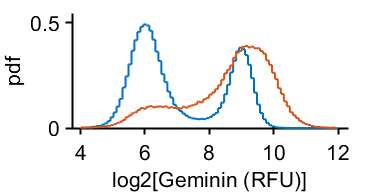

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
% vline([ 9])
print_pdf([pwd() '\Figs\gemininhists.pdf'])


data

data = 1×2 cell array
    {147420×1 double}    {150706×1 double}


**stat test EdU comparison DMSO/DOX zeroed**

Gate for early mitosis, first .3 hrs, high/low geminin

rng(2)
xval = 'YFP1';
yval = 'YFP2';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = dat(condition).(yval) - gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,1) <= 1.5 & dat(condition).POI_time(:,1) >= 1 & ...
    dat(condition).FarRed1 < gate.FarRed1_G1(2) & dat(condition).YFP1 > 2^7  & dat(condition).dna < 2^21.5;
ydata = ydata(inds);

inds = randsample(length(ydata),700);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = dat(condition).(yval)- gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,3) <= .5 & dat(condition).FarRed1 < 2^10 & dat(condition).dna < 2^21.5 ...
    & dat(condition).YFP1 > 2*gate.YFP1_S(2);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^9 ...
    & dat(condition).allFarRed1 < 2^11 & dat(condition).allYFP1 < gate.YFP1_G1(1);
ydata = dat(condition).allYFP2(ind) - gate.YFP2_G1(1);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = ally/median(ally(group == 3));
median(ally(group==2))

ans = 0.1038

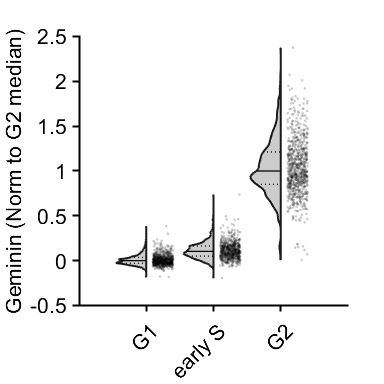

%test = cellfun(@(x) x/median(test{3}),test,'UniformOutput',false);

% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% notBoxPlot((ally),group)

% jit = 0.5*(rand(size(group))-0.5);
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% scatter(group+jit, (ally), 10,'k','filled','MarkerFaceAlpha',.2);
% xlim([0 max(group)+1])
% 
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% violinPlot((ally),'groups',group, 'showMM',5,'histOpt',1,'divFactor',1.5)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('Geminin (Norm to G2 median)')
% ylim([0 2.25])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\C205_gmnn_compare_scatter_zero.pdf'])

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

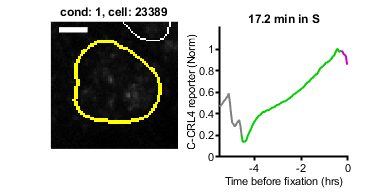

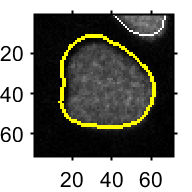

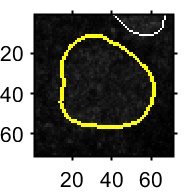

    {'4_9_25'}    {' x:1631, y:1697'}



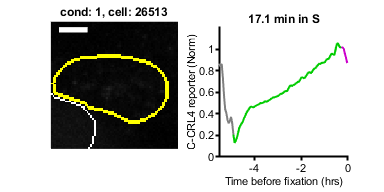

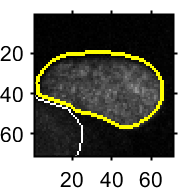

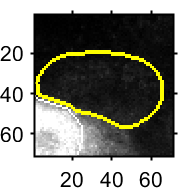

    {'4_10_26'}    {' x:1301, y:966'}



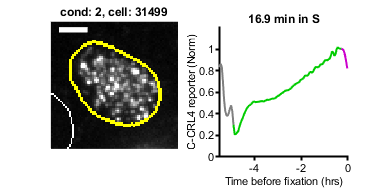

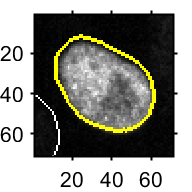

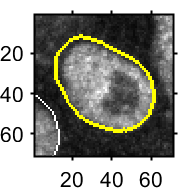

    {'5_11_28'}    {' x:837, y:954'}



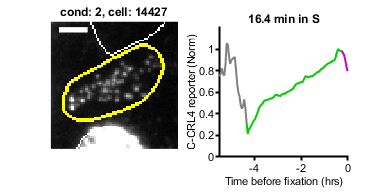

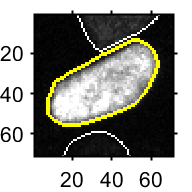

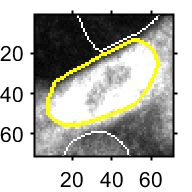

    {'5_6_13'}    {' x:1003, y:189'}



conds=[1 2];
poi_align = 4;
sizeBox = 35;
max_cells = 2;
rng(10)
range1 = [0 300];
range2 = [0 500];
range3 = [0 300];

pixel_size = .625; %um/pixel
bar_length = 10/pixel_size;
exclude = {[19611, 16365, 29123 1248, 18899, 27116],[12705, 8857,31857]};
g1col = [0 .8 0];
scol = [.8 0 .8];
smooth_size = 5;
postbuff = 4;
filtPoints = floor((smooth_size - 1)/2);

for cond = conds
    ind = dat(cond).POI_time(:,poi_align) >= 0/60 & dat(cond).POI_time(:,poi_align) <= 19/60 & dat(cond).POI(:,1) < 1.25*dat(cond).framesPerHr;
    if cond == 2
        ind = ind & dat(cond).YFP2 > 2^9;
    else
        ind = ind & dat(cond).YFP2 < gate.YFP2_G1(2);
    end
    cells = find(ind);
    cells = cells(~ismember(cells,exclude{cond}));
    num_cells = min([max_cells length(cells)]);
    rsamp = randsample(length(cells),num_cells);
    cells = cells(rsamp);
    
    for i = 1:length(cells)
        c = cells(i);
        %crlNuc = nansmoothm(dat(cond).crlNormAct(c,:),5,'sgolay');
        crlNuc = smoothdata(dat(cond).crlNormAct(c,:),2, 'sgolay',[filtPoints min([postbuff, filtPoints ])], 'omitnan','degree',3);
        offset = max(dat(1).xTime) + (dat(cond).POI_time(c,poi_align) - (dat(cond).numFrames - dat(cond).POI(c,poi_align))/dat(cond).framesPerHr) ;

        
        
        shot = [num2str(dat(cond).fixedRow(c)),'_',num2str(dat(cond).fixedCol(c)),'_',num2str(dat(cond).fixedSite(c))];
        x = (dat(cond).x(c))/1;
        y = (dat(cond).y(c))/1;
        pois = dat(cond).POI(c,:);
        
%         move_folder = fullfile(dataDir,'C205_Images',shot,filesep);
%         mkdir(move_folder)        
%         copyfile([impath shot '\' shot '_mask.tif'],[move_folder '\' shot '_mask.tif'])
%         copyfile([impath shot '\' shot '_YFP__round1.tif'],[move_folder '\' shot '_YFP__round1.tif'])
%         copyfile([impath shot '\' shot '_FarRed__round1.tif'],[move_folder '\' shot '_FarRed__round1.tif'])
%         copyfile([impath shot '\' shot '_YFP__round2.tif'],[move_folder '\' shot '_YFP__round2.tif'])

        im1=imread([impath shot '\' shot '_mask.tif']);
        im2=imread([impath shot '\' shot '_YFP__round1.tif']);
        im3=imread([impath shot '\' shot '_FarRed__round1.tif']);
        im4=imread([impath shot '\' shot '_YFP__round2.tif']);
        
        im1_fill = imfill(im1,'holes');
        im1_label = bwlabel(im1_fill);
        cell_label = im1_label(round(y),round(x));
        cell_mask = im1_label == cell_label;
        cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
        
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        im4crop= imcrop(im4,[xmin ymin width height]);
        cell_crop = imcrop(cell_bord,[xmin ymin width height]);
        
        figure('units','inches','Position',[0 0 2*2 2])
        subplot(1,2,1)
        hold on
        b = mat2gray(im3crop,range2);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
        set(gca,'FontSize',8)
%         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
        t=title(sprintf('cond: %d, cell: %d',cond,c),'FontSize',8);
        set(t,'interpreter','none');
        
        subplot(1,2,2)
                xlim([-2 0])   
        ylim([0 1.2])
        hold on

        plot(dat(1).xTime(1:pois(1)) - offset, crlNuc(1:pois(1)),'Color',[.5 .5 .5]);
        plot(dat(1).xTime(pois(1):pois(poi_align)) - offset, crlNuc(pois(1):pois(poi_align)),'Color',g1col);
        plot(dat(1).xTime(pois(poi_align):end) - offset, crlNuc(pois(poi_align):end),'Color',scol);        
        set(gca,'FontSize',8)
 
        
        
        
        title(sprintf('%.1f min in S',dat(cond).POI_time(c,poi_align)*60),'FontSize',8)
        xlabel('Time before fixation (hrs)','FontSize',8)
        ylabel('C-CRL4 reporter (Norm)','FontSize',8)
        ylim([0 1.2])
        xlim([-5.5 0])
        axis square
        print_pdf([pwd() '\Figs\cells\images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
        
        imwrite(b,[pwd() '\Figs\cells\small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        
                b = mat2gray(im2crop,range1);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        figure('units','inches','Position',[0 0 2 2]), imagesc(b)
        imwrite(b,[pwd() '\Figs\cells\Cdt1_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        
         b = mat2gray(im4crop,range3);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        figure('units','inches','Position',[0 0 2 2]), imagesc(b)
        imwrite(b,[pwd() '\Figs\cells\GMNN_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        
        disp({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]});

    end

end

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

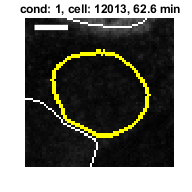

    {'4_6_10'}    {' x:1872, y:1553'}



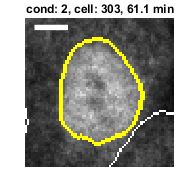

    {'5_2_12'}    {' x:223, y:261'}



conds=[1 2];
poi_align = 1;
sizeBox = 35;
max_cells = 1;
rng(1)
% range1 = [0 300];
range2 = [0 400];
pixel_size = .625; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[]};
g1col = [0 .8 0];
scol = [.8 0 .8];
offset = max(dat(1).xTime);

for i = 1:length(conds)
    cond = conds(i);
    ind = dat(cond).POI_time(:,poi_align) <= 1.05  & dat(cond).POI_time(:,poi_align) > 1;
    if cond == 2
        ind = ind & dat(cond).YFP2 > 2^9;
    end
    cells = find(ind);
    cells = cells(~ismember(cells,exclude{cond}));
    num_cells = min([max_cells length(cells)]);
    rsamp = randsample(length(cells),num_cells);
    cells = cells(rsamp);
    
    for i = 1:length(cells)
        c = cells(i);
        crlNuc = nansmoothm(dat(cond).crlNormAct(c,:),7,'sgolay');
        shot = [num2str(dat(cond).fixedRow(c)),'_',num2str(dat(cond).fixedCol(c)),'_',num2str(dat(cond).fixedSite(c))];
        x = (dat(cond).x(c))/1;
        y = (dat(cond).y(c))/1;
        pois = dat(cond).POI(c,:);
        
        
%         move_folder = fullfile(dataDir,'C205_Images',shot,filesep);
%         mkdir(move_folder)        
%         copyfile([impath shot '\' shot '_mask.tif'],[move_folder '\' shot '_mask.tif'])
%         copyfile([impath shot '\' shot '_YFP__round1.tif'],[move_folder '\' shot '_YFP__round1.tif'])
%         copyfile([impath shot '\' shot '_FarRed__round1.tif'],[move_folder '\' shot '_FarRed__round1.tif'])
%         copyfile([impath shot '\' shot '_YFP__round2.tif'],[move_folder '\' shot '_YFP__round2.tif'])

        im1=imread([impath shot '\' shot '_mask.tif']);
        im3=imread([impath shot '\' shot '_YFP__round2.tif']);
%         im3=imread([impath shot '\' shot '_FarRed__round1.tif']);
        im1_fill = imfill(im1,'holes');
        im1_label = bwlabel(im1_fill);
        cell_label = im1_label(round(y),round(x));
        cell_mask = im1_label == cell_label;
        cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
  
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
%         im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        cell_crop = imcrop(cell_bord,[xmin ymin width height]);
        
        figure('units','inches','Position',[0 0 2 2])
%         subplot(1,1,1)
        b = mat2gray(im3crop,range2);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        imagesc(b);
        hold on
        axis off
        axis square

        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)

%         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
        t=title(sprintf('cond: %d, cell: %d, %.1f min',cond,c,dat(cond).POI_time(c,poi_align)*60));
        set(gca,'FontSize',8)
        set(t,'interpreter','none');
        print_pdf([pwd() '\Figs\cells\gmnn_images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])

        imwrite(b,[pwd() '\Figs\cells\small_gmnn_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
           
        disp({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]});

    end

end  

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

poi_align = 1;
sizeBox = 35;
max_cells = 1;
rng(1)
% range1 = [0 300];
range2 = [0 500];
pixel_size = .625; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[]};
g1col = [0 .8 0];
scol = [.8 0 .8];
offset = max(dat(1).xTime);

   cond =1  

cond = 1

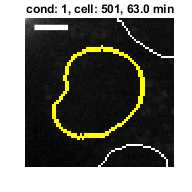

        c = 501;
        crlNuc = nansmoothm(dat(cond).crlNormAct(c,:),7,'sgolay');
        shot = [num2str(dat(cond).fixedRow(c)),'_',num2str(dat(cond).fixedCol(c)),'_',num2str(dat(cond).fixedSite(c))];
        x = (dat(cond).x(c))/1;
        y = (dat(cond).y(c))/1;
        pois = dat(cond).POI(c,:);
        
        
%         move_folder = fullfile(dataDir,'C205_Images',shot,filesep);
%         mkdir(move_folder)        
%         copyfile([impath shot '\' shot '_mask.tif'],[move_folder '\' shot '_mask.tif'])
%         copyfile([impath shot '\' shot '_YFP__round1.tif'],[move_folder '\' shot '_YFP__round1.tif'])
%         copyfile([impath shot '\' shot '_FarRed__round1.tif'],[move_folder '\' shot '_FarRed__round1.tif'])
%         copyfile([impath shot '\' shot '_YFP__round2.tif'],[move_folder '\' shot '_YFP__round2.tif'])

        im1=imread([impath shot '\' shot '_mask.tif']);
%         im3=imread([impath shot '\' shot '_YFP__round2.tif']);
        im3=imread([impath shot '\' shot '_FarRed__round1.tif']);
        im1_fill = imfill(im1,'holes');
        im1_label = bwlabel(im1_fill);
        cell_label = im1_label(round(y),round(x));
        cell_mask = im1_label == cell_label;
        cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
  
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
%         im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
        cell_crop = imcrop(cell_bord,[xmin ymin width height]);
        
        figure('units','inches','Position',[0 0 2 2])
%         subplot(1,1,1)
        b = mat2gray(im3crop,range2);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        imagesc(b);
        hold on
        axis off
        axis square

        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)

%         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
        t=title(sprintf('cond: %d, cell: %d, %.1f min',cond,c,dat(cond).POI_time(c,poi_align)*60));
        set(gca,'FontSize',8)
        set(t,'interpreter','none');
        print_pdf([pwd() '\Figs\cells\g1edu_images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])


        imwrite(b,[pwd() '\Figs\cells\small_g1edu_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
           
        disp({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]});

    {'4_2_5'}    {' x:723, y:1155'}

